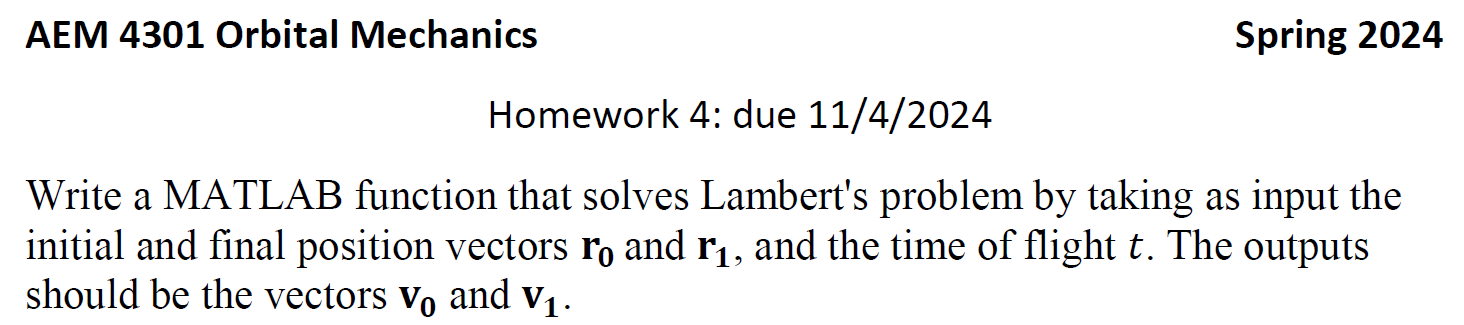

% some code

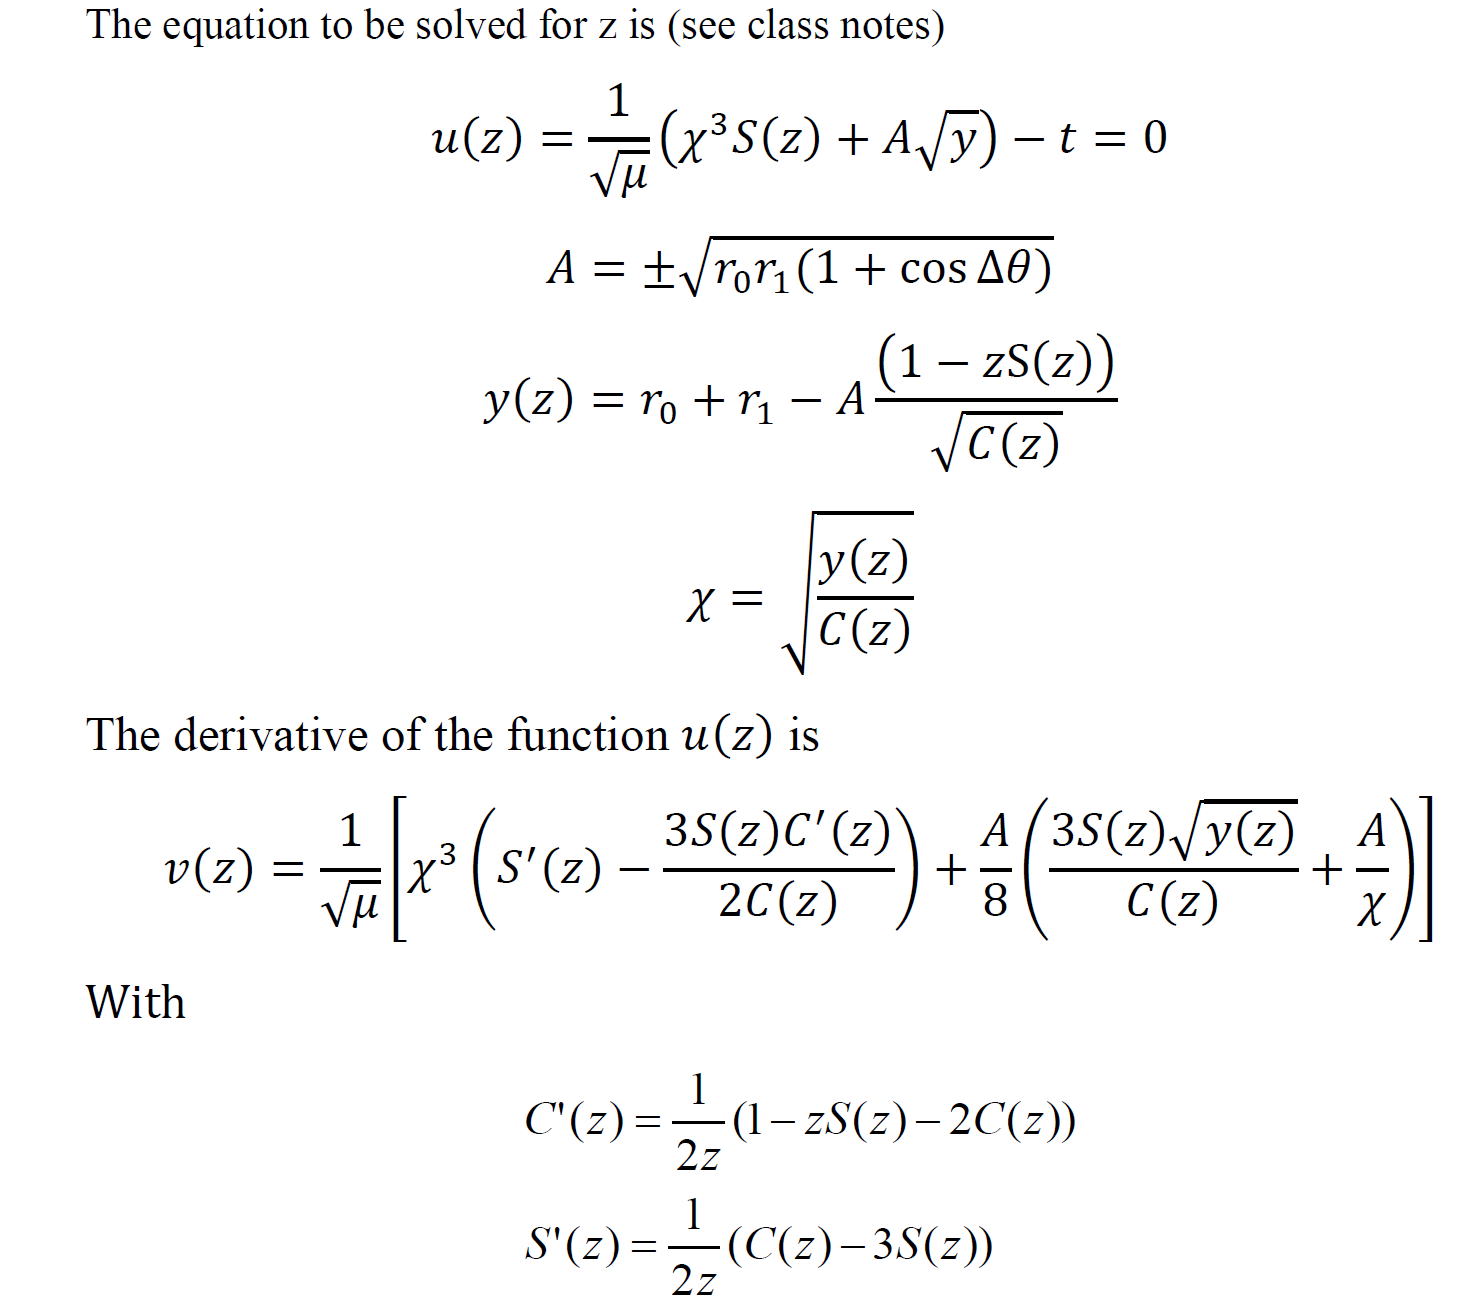

% dot product 
    r0_mag = norm(r0);
    r1_mag = norm(r1);
    
    cos_theta = dot(r0, r1) / (r0_mag * r1_mag);
    theta = acos(cos_theta);

    A = sqrt(r0_mag * r1_mag * (1 + cos_theta))

    z = 0.0;
    %initial guess
    
    % Newton's method loop
    for i = 1:400
    
        y = r0_mag + r1_mag - A * (1 - z * Sz) / sqrt(Cz);
  
        u = (1 / sqrt(mu)) * ((z^3 * Sz + A * sqrt(y)) - t);
        Cprimez = (1 / (2 * z)) * (1 - z * Sz - 2 * Cz);
        Sprimez = (1 / (2 * z)) * (Cz - 3 * Sz);
        v = (1 / sqrt(mu)) * ( ...
            z^3 * (Sprimez - 3 * Sz * Cprimez / (2 * Cz)) + ...
            (A / 8) * ((3 * Sz * sqrt(y) / Cz) + (A / sqrt(y / Cz))));
        z = z - u / v;
    end



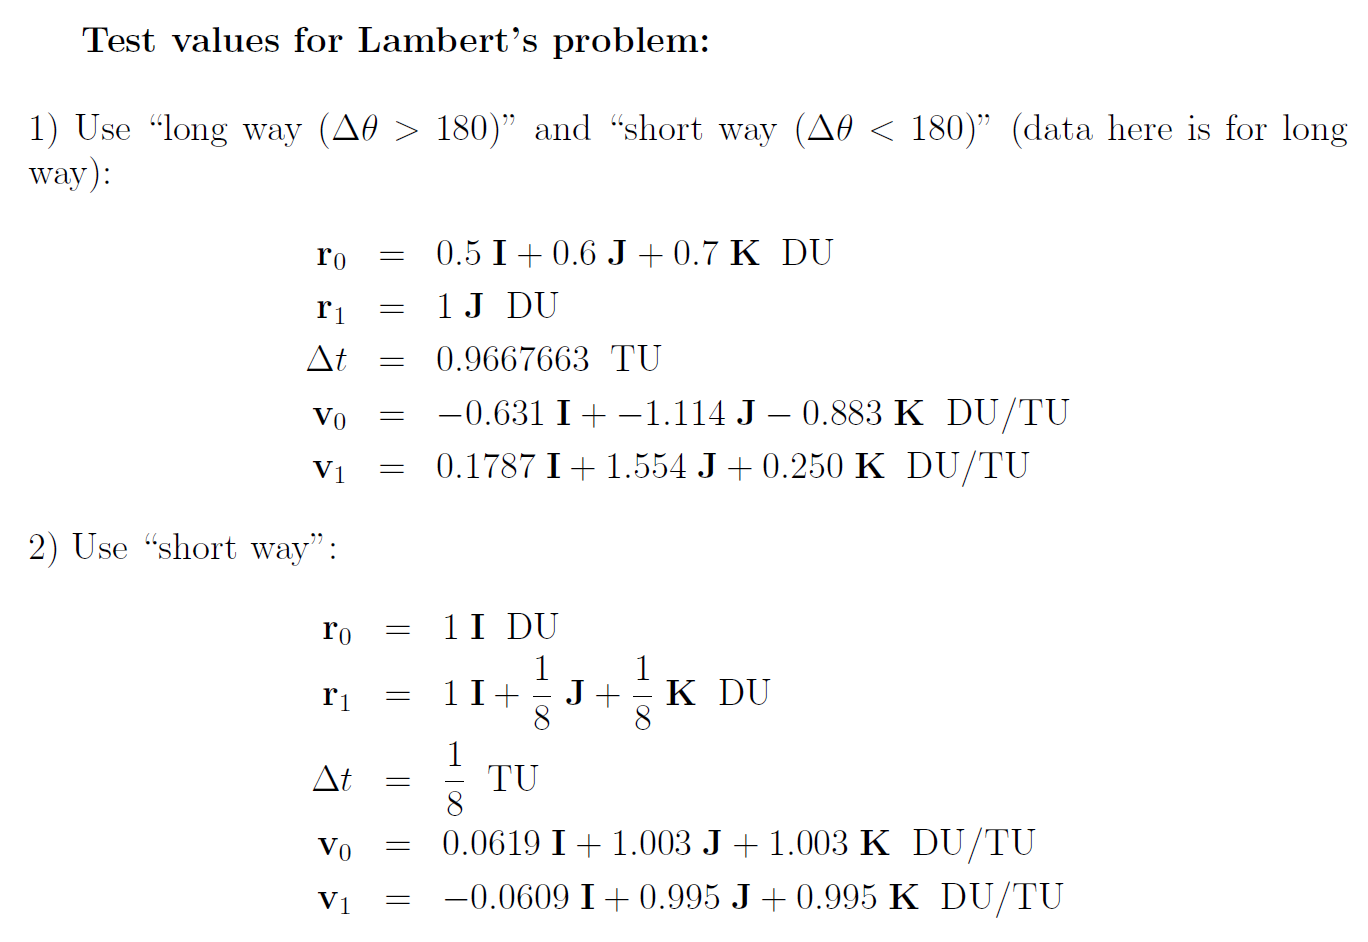

% testing code
